v = VideoReader("shuttle.avi");

img1 = read(v, 1);
img2 = read(v, 118);

BW1 = rgb2gray(img1) > 245;
maskedImg1 = img1;
maskedImg1(~BW1) = 0;
maskedImg1(BW1) = 1;

BW2 = rgb2gray(img2) > 245;
maskedImg2 = img2;
maskedImg2(~BW2) = 0;
maskedImg2(BW2) = 1;

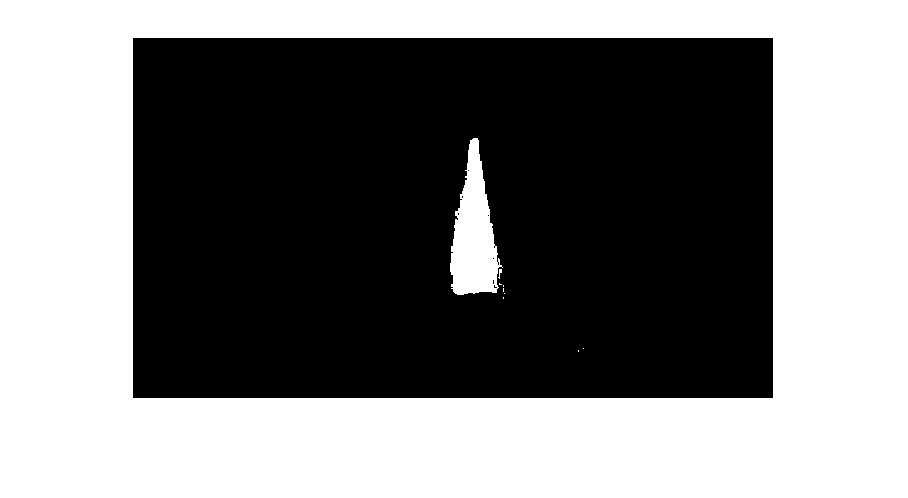

imshow(BW2)

nnz(maskedImg2) - nnz(maskedImg1)

ans = 2605

nnz(BW2) - nnz(BW1)

ans = 2552

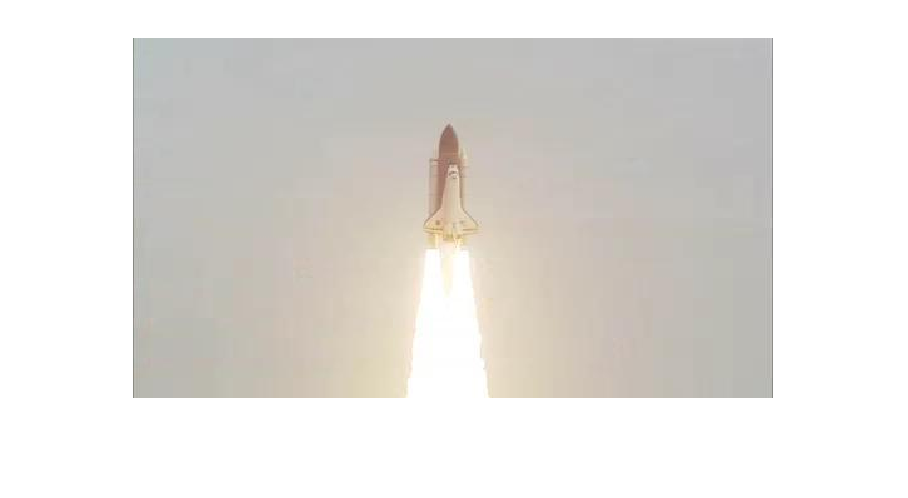

imshow(read(v, 119))

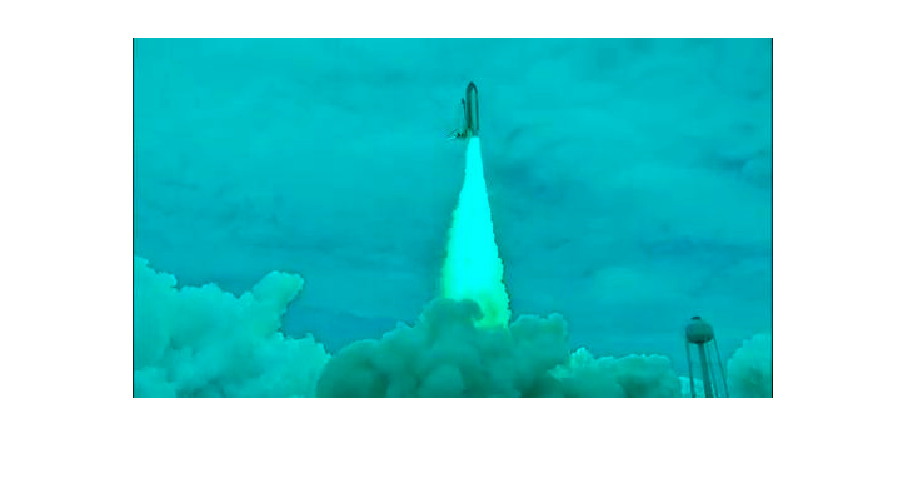

imshow(maskedImg2)

v = VideoReader("liquidVideo.mp4");

background = im2double(read(v, 1));

img  = read(v, 175);

frameDiff = abs(im2double(img) - background);
frameDiffGray = im2gray(frameDiff);
BW = imadjust(frameDiffGray);
BW = im2gray(BW) > 4.400000e-01;
% Erode mask with default
radius = 5;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imerode(BW, se);

% Dilate mask with default
radius = 5;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imdilate(BW, se);

nnz(BW)

ans = 15691

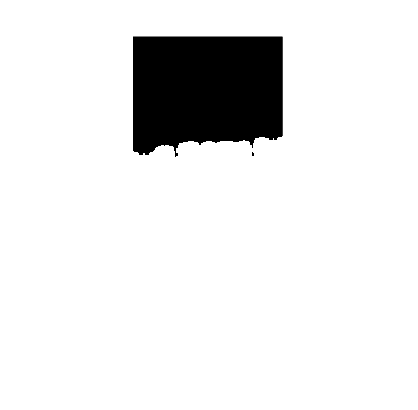

imshow(BW)

frame = 16.7 * 10

frame = 167

v.FrameRate

ans = 10

imgFinal = read(v, 167);

frameDiff = abs(im2double(imgFinal) - background);
frameDiffGray = im2gray(frameDiff);
BW = imadjust(frameDiffGray);
BW = im2gray(BW) > 4.400000e-01;
% Erode mask with default
radius = 5;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imerode(BW, se);

% Dilate mask with default
radius = 5;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imdilate(BW, se);

nnz(BW(:, 1)) * 3.4/height(BW)ccleaasasasaopooosaa

ans = 1.8889

ans = 1.9519

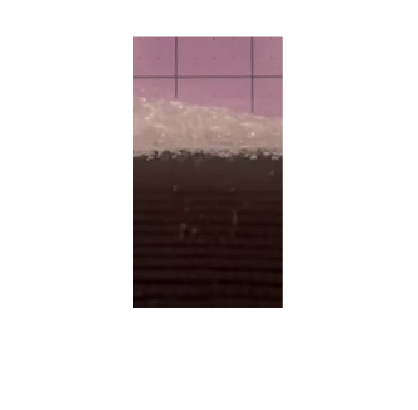

imshow(imgFinal)